# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 4 part 2: exercise 04 - Derive Statistics from GLCM and Plot Correlation

## Questions 

## 1) Entropy

- Calculate the entropy, using the `entropy` function, from the list of images and sort  them, using the `sort` function, from lowest to highest entropy  (step 2).

- Which image has the lowest entropy and why? Draw conclusions.

## 2) Co-occurrence matrix

- Read the help of  `graycomatrix` function to understand all its parameters. [https://es.mathworks.com/help/images/ref/graycomatrix.html](https://es.mathworks.com/help/images/ref/graycomatrix.html)

- Define offsets of varying direction ( 0º, 45º, 90º, 135º) and length (len=5).  

- Create a set of GLCMs, using `graycomatrix` function specifying the offsets for textures: `'texture-linseeds.png'` and `'texture-pattern2.png'`.

- Displays the image of the first GLCM with scaled colors, use the following code properly adapted:

% imagesc(glcm)
% colormap jet
% colorbar

## 3) Co-occurrence matrix statistics.

- Obtain statistics from the GLCMs using the `graycoprops` function for the previous textures: `'texture-linseeds.png'` and `'texture-pattern2.png'`..

- Plot one of following statistic: `Contrast, Correlation, Energy, Homogeneity`, as a function of offset.

Step 1) Read Image

clear all
close all

imagenames = {'texture-stone.png','texture-sand.png','texture-linseeds.png', ...
              'texture-canvas.png','texture-pattern1.png','texture-pattern2.png'};

textureImg=[];
for n=1:length(imagenames)
    textureImg{n} = imread(imagenames{n});
end

Step 2) Entropy

% Entropy is defined as -sum(p.*log2(p)), where p contains the normalized histogram counts returned from imhist.
for n=1:length(imagenames)
    entropia{n} = entropy(textureImg{n});
end

a = cell2mat(entropia);

[sortedEntropy,sortId]= sort(a,'ascend')

sortedEntropy =     4.1983    4.7936    5.9055    6.5980    6.8046    7.2660


sortId =      6     5     4     2     1     3


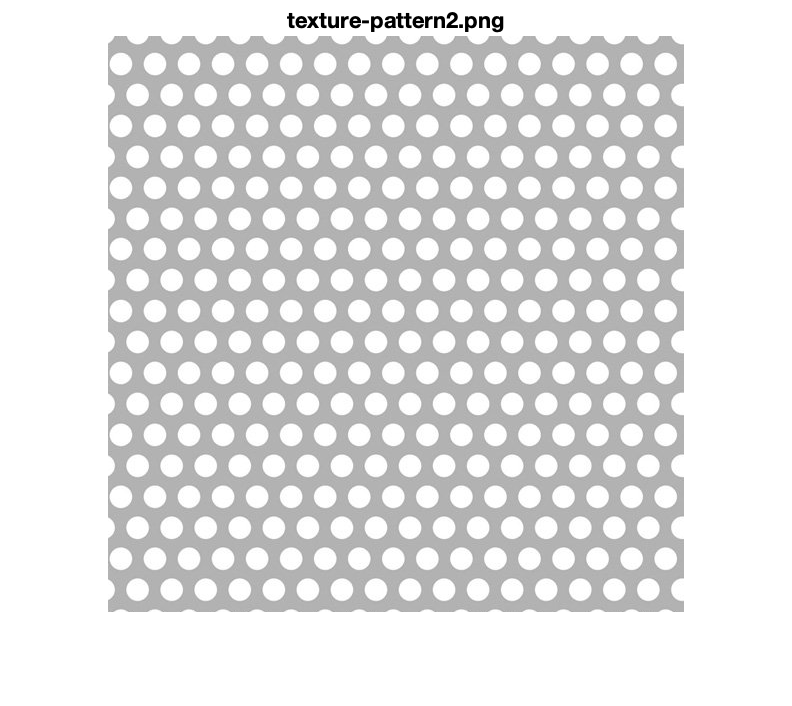

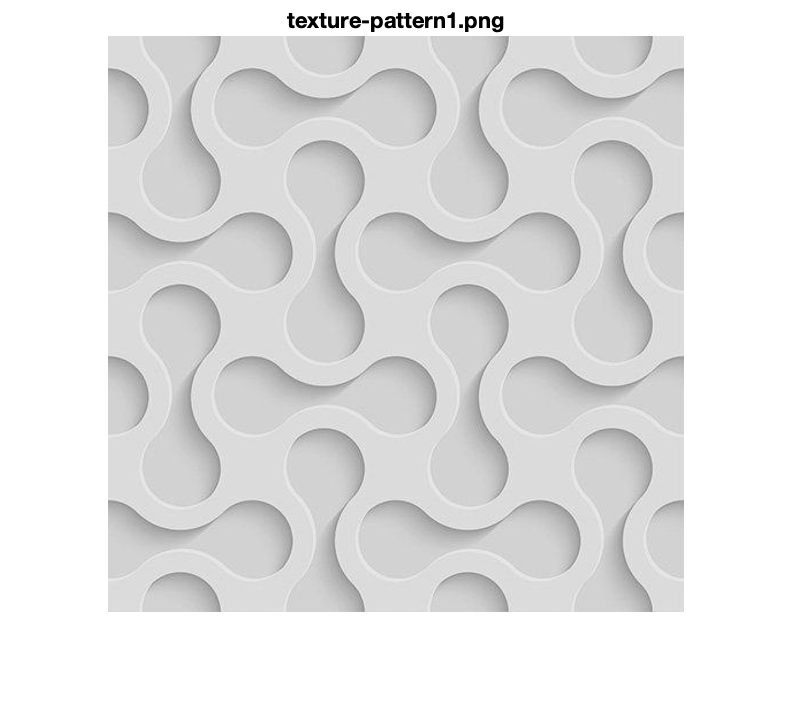

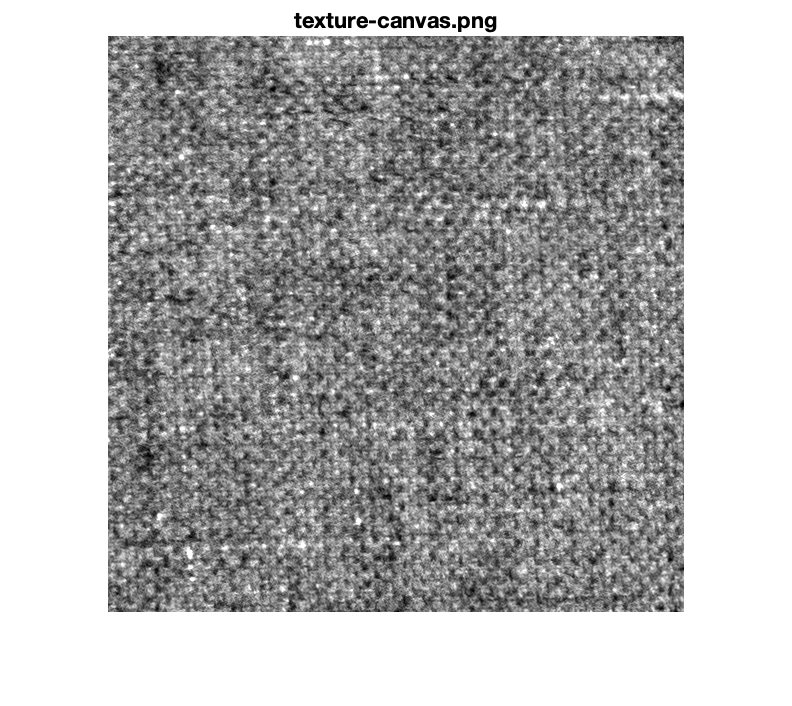

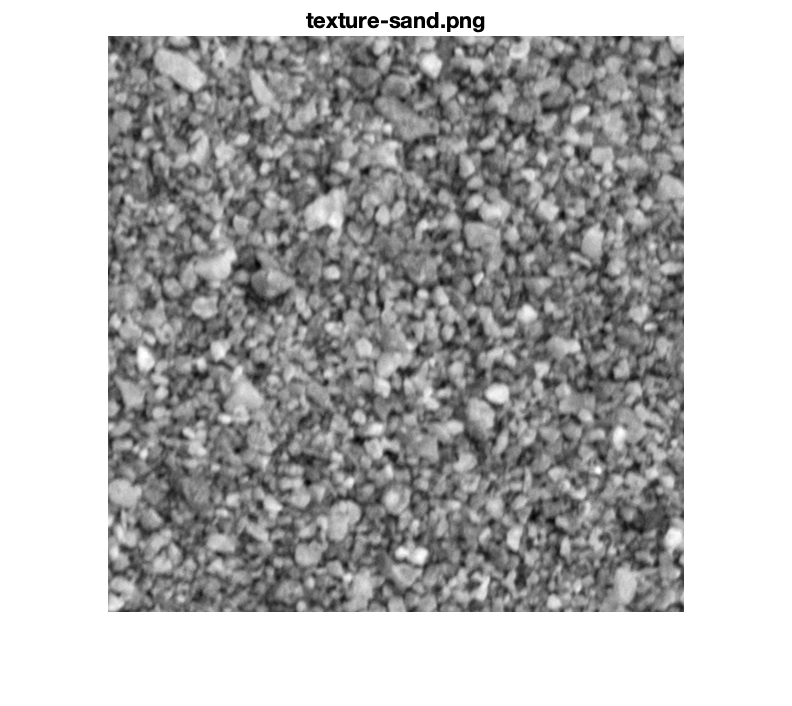

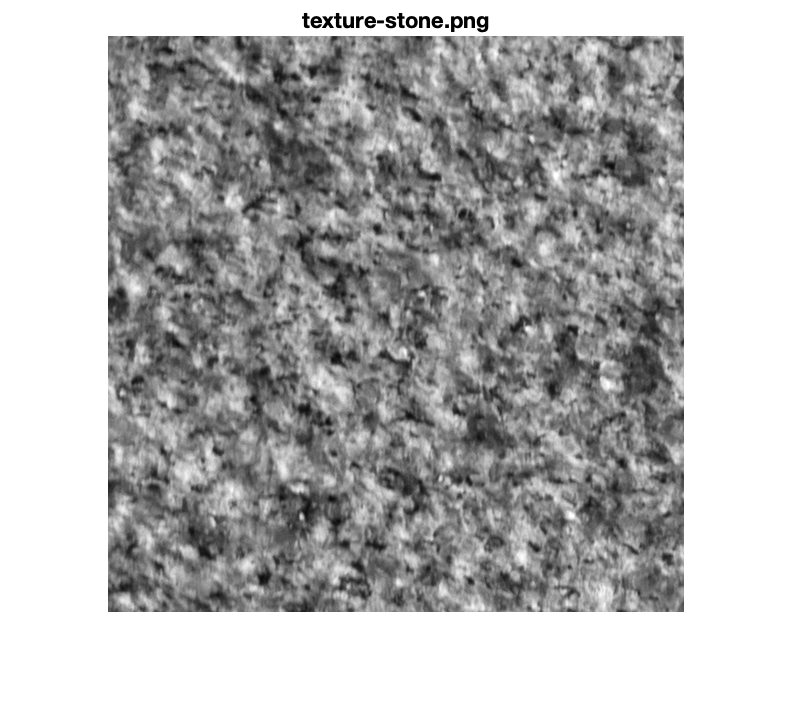

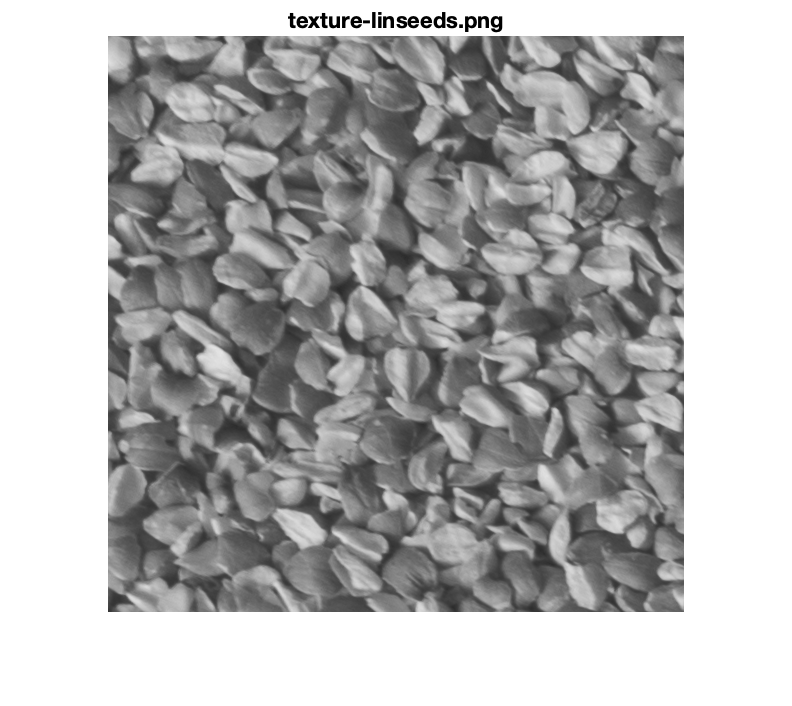

%Mostramos las imagenes por orden de entropia
for n=1:length(entropia)
    figure, imshow(textureImg{sortId(n)}), title(imagenames{sortId(n)});    
end

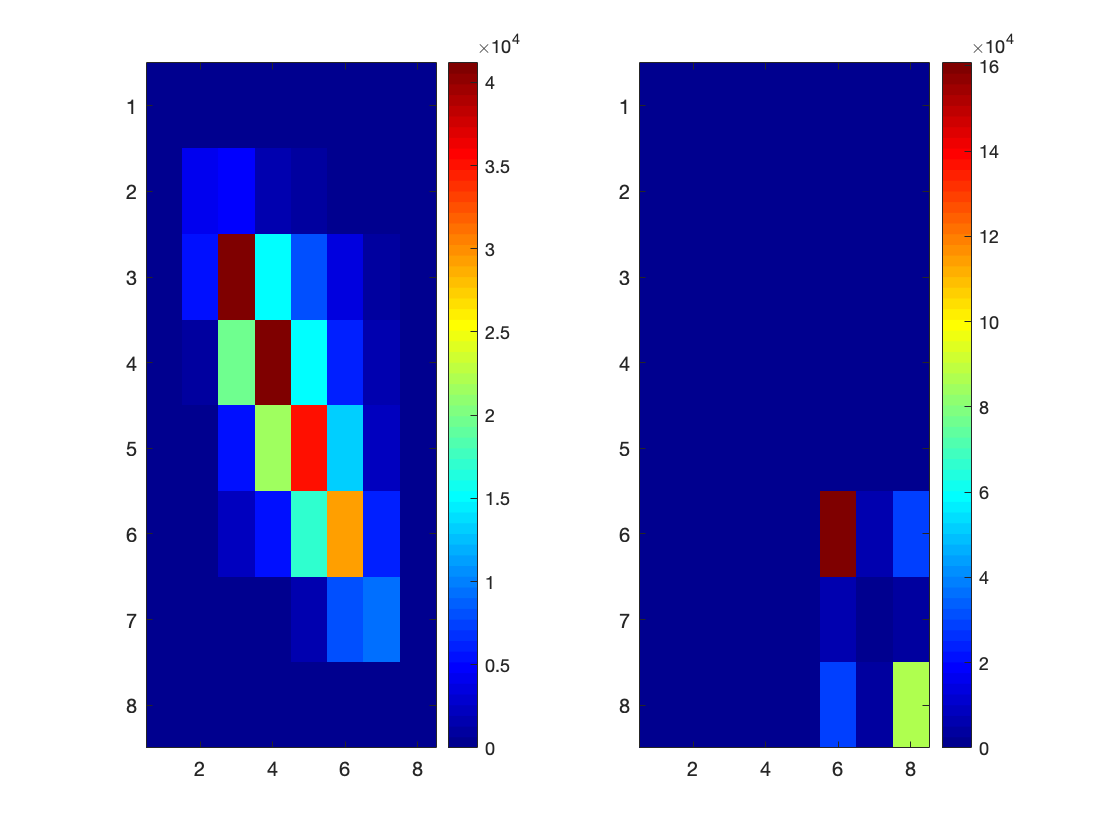

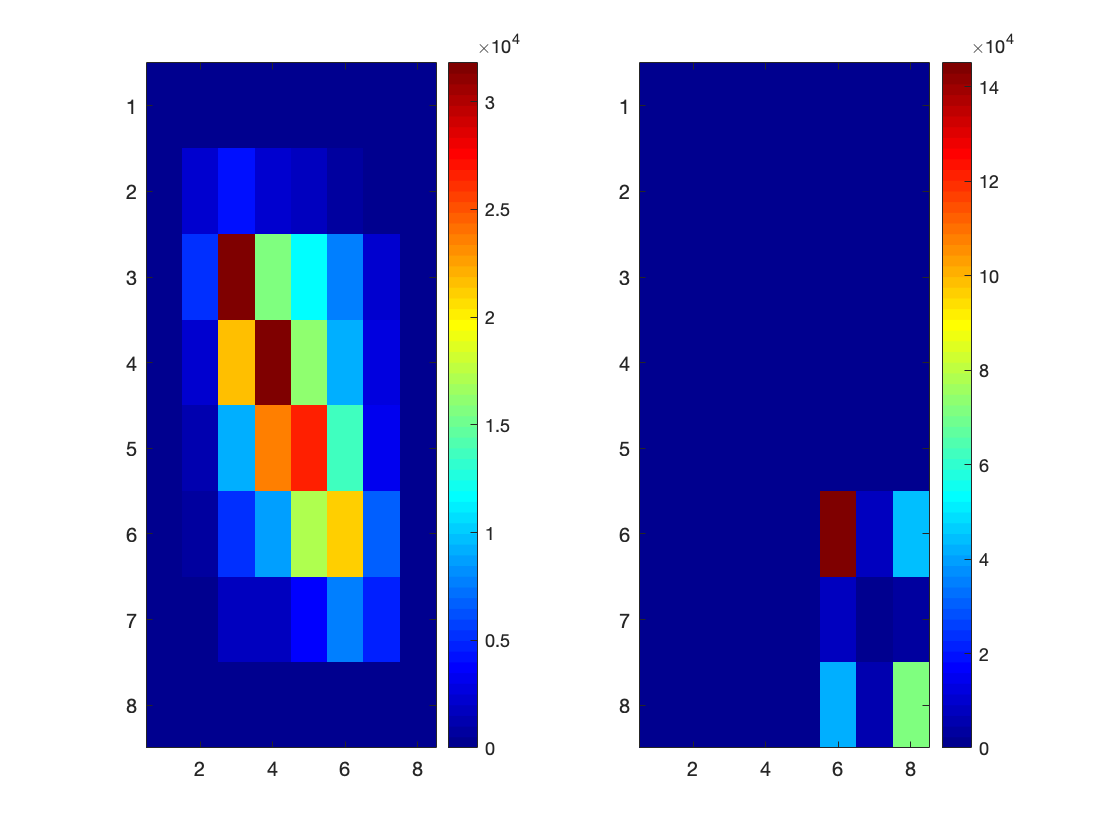

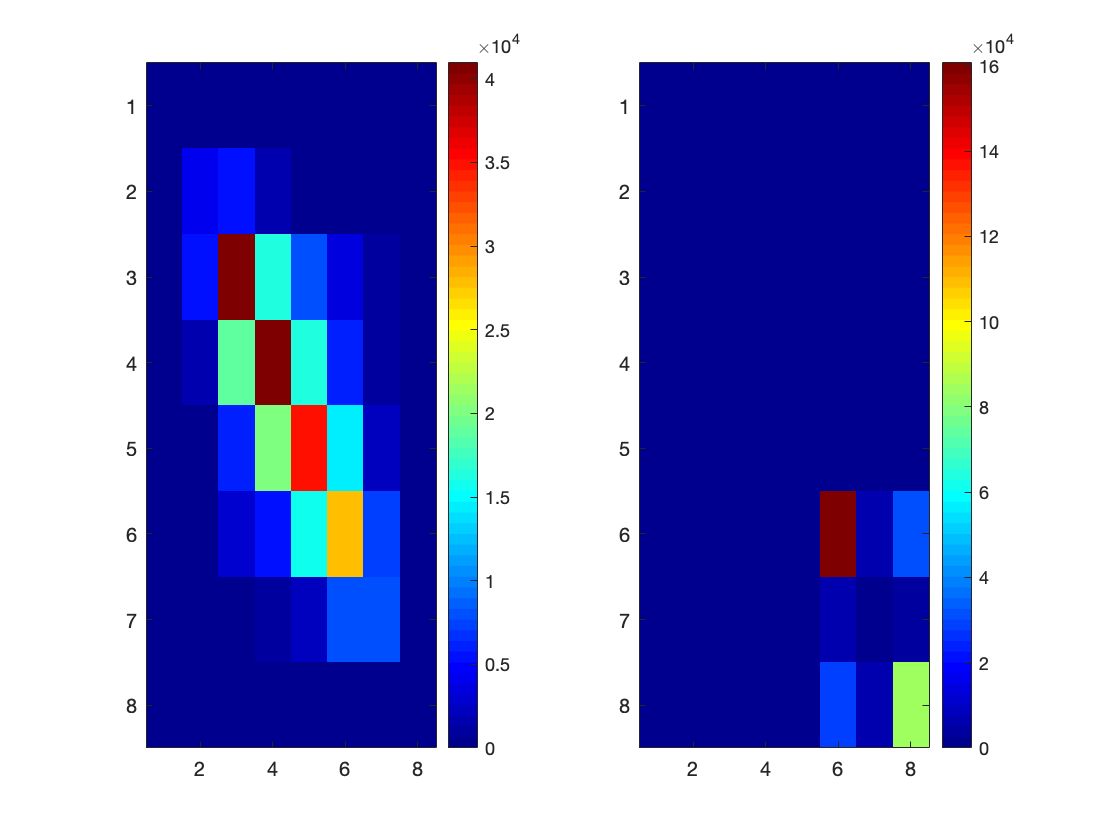

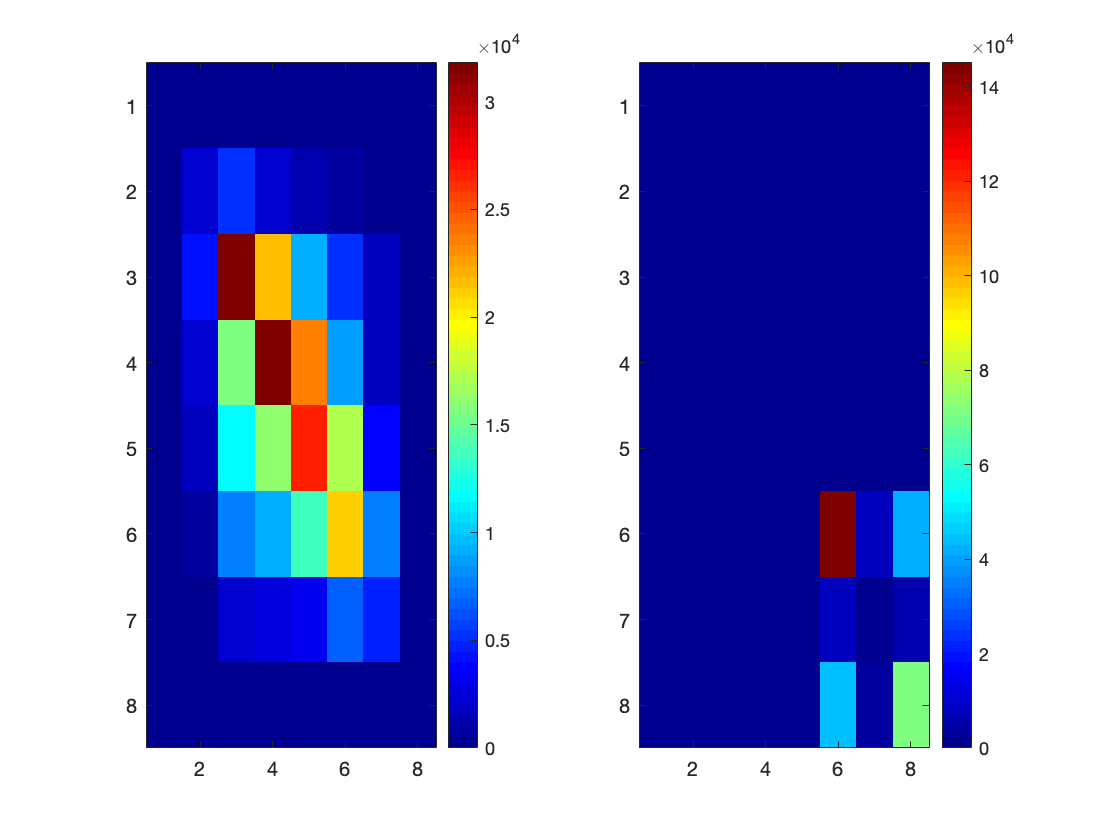

len = 5;
% [row_offset, col_offset]
offsets= {[0 len];[-len len];[-len 0];[len -len]};
offsets_ang= {0;45;90;135};

%co-ocurrence matrix
for i=1:length(offsets)
    matrices1{i}=graycomatrix(textureImg{3},'Offset',offsets{i});
    matrices6{i}=graycomatrix(textureImg{6},'Offset',offsets{i});
    i=i+1;
end

for i=1:length(matrices1)
     figure;
     subplot(1,2,1), imagesc(matrices1{i}),colormap jet, colorbar;
     subplot(1,2,2), imagesc(matrices6{i}),colormap jet, colorbar;
end

Step 3) co-ocurrence matrix

%co-ocurrence matrix
%co=graycoprops(textureImg{1})
%c.Contrast
graycoprops(textureImg{6})

ans = struct with fields:
       Contrast: 5.5195e+04
    Correlation: 1.2130e-04
         Energy: 3.1051e-06
    Homogeneity: 0.0189


Displays the image of the first GLCM with scaled colors

Step 4) statistics

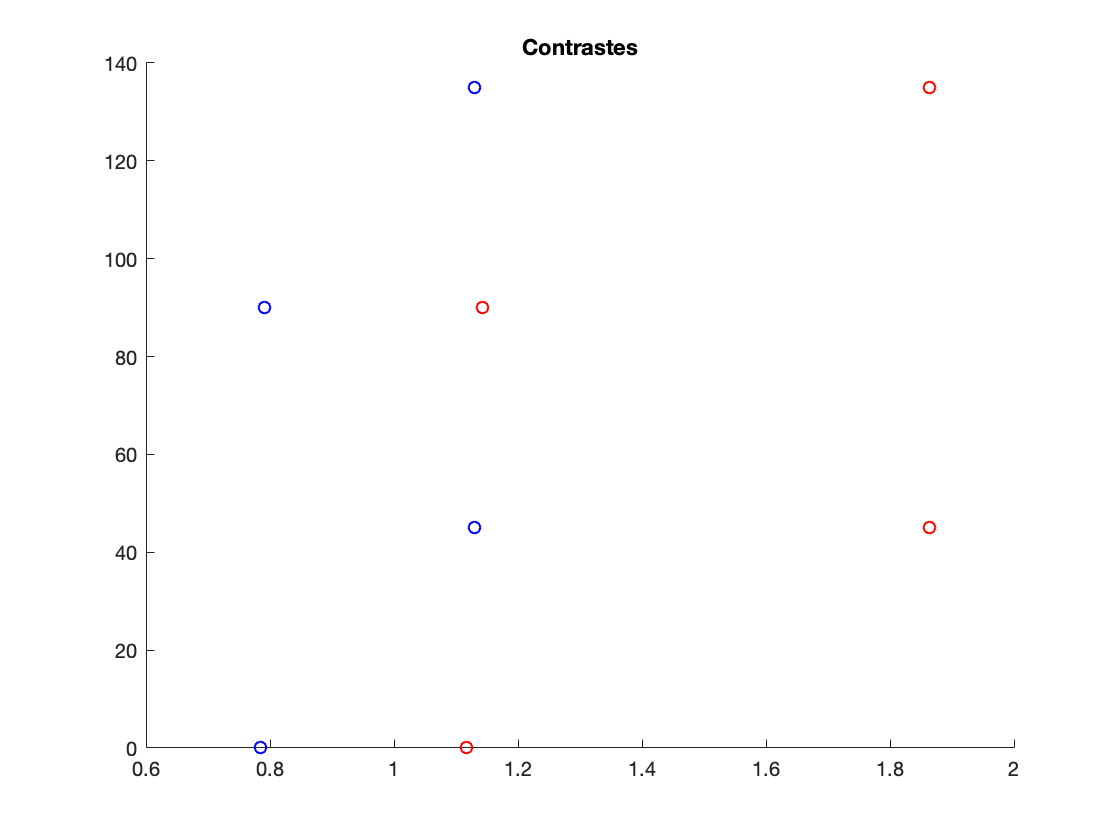


for i=1:length(offsets)
    props3{i}=graycoprops(matrices1{i});
    props6{i}=graycoprops(matrices6{i});
end

figure;
title('Contrastes');
hold on;

for i=1:length(offsets) 
    scatter(props3{i}.Contrast,offsets_ang{i},'red')
    scatter(props6{i}.Contrast,offsets_ang{i},'blue')
    hold on
end

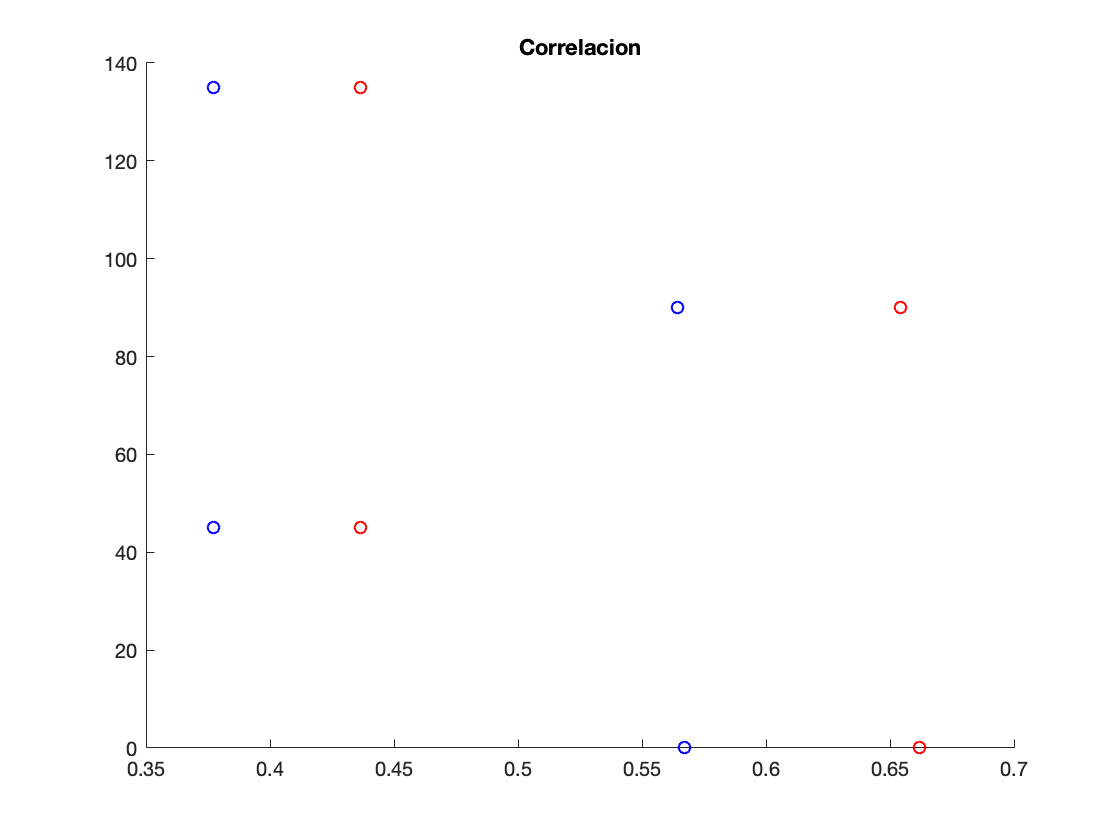



figure;
title('Correlacion');
hold on;

for i=1:length(offsets)
    scatter(props3{i}.Correlation,offsets_ang{i},'red')
    scatter(props6{i}.Correlation,offsets_ang{i},'blue')
    hold on
end

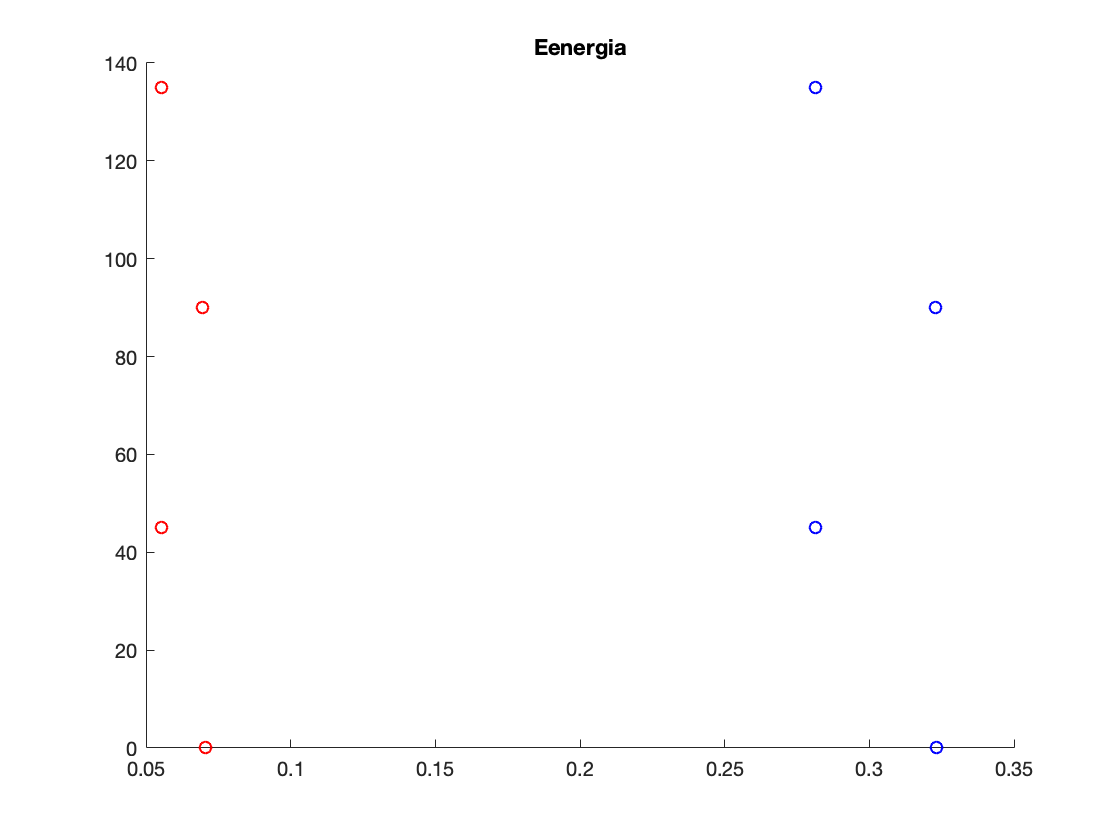



figure,
title('Eenergia');
hold on;
for i=1:length(offsets)  
    scatter(props3{i}.Energy,offsets_ang{i},'red')
    scatter(props6{i}.Energy,offsets_ang{i},'blue')
    hold on
end

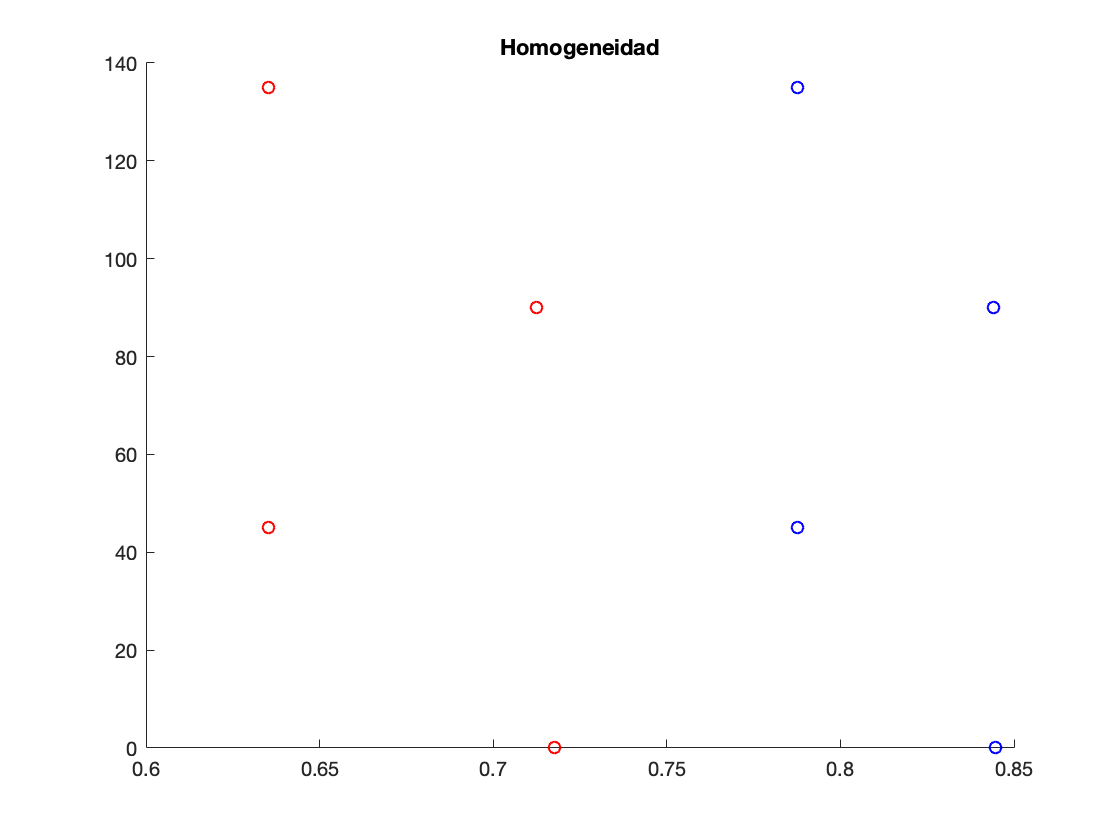


figure
title('Homogeneidad');
hold on;
for i=1:length(offsets)
   
    scatter(props3{i}.Homogeneity,offsets_ang{i},'red')
    scatter(props6{i}.Homogeneity,offsets_ang{i},'blue')
    hold on
end

props6{1}

ans = struct with fields:
       Contrast: 0.7854
    Correlation: 0.5673
         Energy: 0.3233
    Homogeneity: 0.8446
